close all
clear variables
spectra = importdata("spectra.csv")

spectra = 	1.0e+-12 *

    0.3088    0.1340    0.0598    0.0892    0.1088    0.1625    0.0392
    0.3136    0.1338    0.0607    0.0898    0.1084    0.1630    0.0382
    0.3105    0.1347    0.0618    0.0915    0.1104    0.1615    0.0371
    0.3076    0.1357    0.0625    0.0931    0.1124    0.1586    0.0378
    0.3088    0.1354    0.0627    0.0936    0.1122    0.1574    0.0391
    0.3105    0.1343    0.0622    0.0932    0.1136    0.1589    0.0396
    0.3122    0.1335    0.0619    0.0929    0.1138    0.1611    0.0402
    0.3101    0.1325    0.0620    0.0925    0.1130    0.1607    0.0399
    0.3078    0.1335    0.0626    0.0924    0.1124    0.1593    0.0387
    0.3047    0.1329    0.0625    0.0918    0.1108    0.1582    0.0379


lambdaStart = importdata("lambda_start.csv")

lambdaStart = 630.0200

lambdaDelta = importdata("lambda_delta.csv")

lambdaDelta = 0.1400

starNames = importdata("star_names.csv")

starNames = 7×1 cell array
    {'HD30584'  }
    {'HD10032'  }
    {'HD64191'  }
    {'HD5211'   }
    {'HD56030'  }
    {'HD94028'  }
    {'SAO102986'}



sped_of_light = 299792.458

sped_of_light = 2.9979e+05


nObs = size(spectra, 1)

nObs = 357

nSts = size(spectra, 2)

nSts = 7

lambdaEnd = lambdaStart + (nObs-1) * lambdaDelta

lambdaEnd = 679.8600

lambda = (lambdaStart : lambdaDelta : lambdaEnd)'

lambda =   630.0200
  630.1600
  630.3000
  630.4400
  630.5800
  630.7200
  630.8600
  631.0000
  631.1400
  631.2800



i=1;
mint = (1 : 1 : nSts);
midx = (1 : 1 : nSts);

while i<=nSts
    [ mint( 1,i ), midx(1,i) ] = min(spectra(:,i));
    i = i+1;
end


i=1

i = 1

speed = (1 : 1 : nSts)'

speed =      1
     2
     3
     4
     5
     6
     7


while i<=nSts
    speed(i,1) = ((lambda(midx(i))/656.28)-1)*sped_of_light
    i=i+1;
end

speed =   -36.5445
    2.0000
    3.0000
    4.0000
    5.0000
    6.0000
    7.0000


speed =   -36.5445
 -100.4973
    3.0000
    4.0000
    5.0000
    6.0000
    7.0000


speed =   -36.5445
 -100.4973
  -36.5445
    4.0000
    5.0000
    6.0000
    7.0000


speed =   -36.5445
 -100.4973
  -36.5445
   27.4083
    5.0000
    6.0000
    7.0000


speed =   -36.5445
 -100.4973
  -36.5445
   27.4083
   27.4083
    6.0000
    7.0000


speed =   -36.5445
 -100.4973
  -36.5445
   27.4083
   27.4083
  155.3139
    7.0000


speed =   -36.5445
 -100.4973
  -36.5445
   27.4083
   27.4083
  155.3139
 -228.4029


fg1 = figure

fg1 =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [489 343 560 420]
       Units: 'pixels'

  Show all properties


j=1

j = 1

i=1

i = 1

for i=1:1:nSts 
    if speed(i)>0
        plot(lambda,spectra(:,i),"-",'LineWidth',3,"Color",[rand(1) rand(1) rand(1)])
    else
        plot(lambda,spectra(:,i),"--",'LineWidth',1,"Color",[rand(1) rand(1) rand(1)])
        moveaway(j) = starNames(i)
        j=j+1
    end
    i=i+1
    hold on
end

moveaway = 1×1 cell array
    {'HD30584'}


j = 2

i = 2

moveaway = 1×2 cell array
    {'HD30584'}    {'HD10032'}


j = 3

i = 3

moveaway = 1×3 cell array
    {'HD30584'}    {'HD10032'}    {'HD64191'}


j = 4

i = 4

i = 5

i = 6

i = 7

moveaway = 1×4 cell array
    {'HD30584'}    {'HD10032'}    {'HD64191'}    {'SAO102986'}


j = 5

i = 8

moveaway

moveaway = 1×4 cell array
    {'HD30584'}    {'HD10032'}    {'HD64191'}    {'SAO102986'}


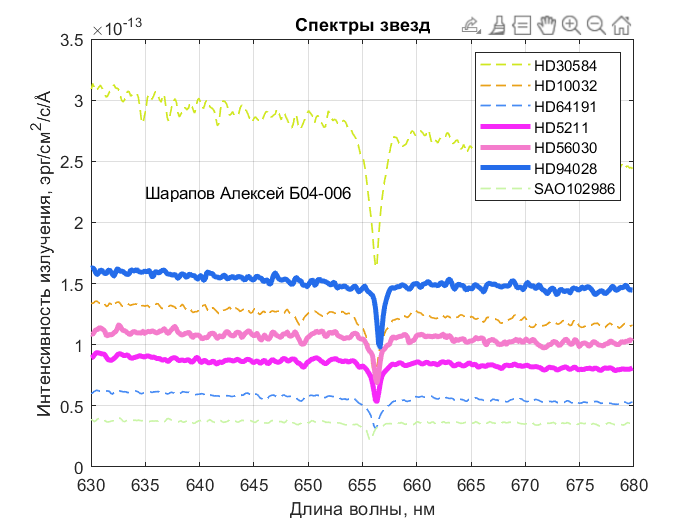

grid on
xlabel('Длина волны, нм')
ylabel(['Интенсивность излучения, эрг/см^2/c/', char(197)])
title('Спектры звезд')
legend(starNames)
text(635,2.25*10^(-13),'Шарапов Алексей Б04-006')
set(fg1, 'Visible',"on")
saveas(fg1, 'spectaplot.png')